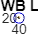

Invalid or deleted object.

% Set up initial parameters for UWB localization
numNodes = 3;
numBlinks = 1;
SNR = 30;  % in dB signal to noise ratio

% Node locations
nodeLoc = [40 41;
           62 83;
           87 24];

% Initialize device location
deviceLoc = [50 50];

% Configure MAC and PHY layers for blink transmission
payload = '00'; 
cfg = lrwpan.MACFrameConfig( ...
        FrameType='Data', ...
        SourceAddressing='Short address', ...
        SourcePANIdentifier='AB12', ...
        SourceAddress='CD77');
blinkMAC = lrwpan.MACFrameGenerator(cfg,payload);

blinkPHYConfig = lrwpanHRPConfig( ...
    Mode='HPRF', ...
    STSPacketConfiguration=1, ...
    PSDULength=length(blinkMAC)/8, ...
    Ranging=true);
blinkPHY = lrwpanWaveformGenerator( ...
    blinkMAC, ...
    blinkPHYConfig);

indices = lrwpanHRPFieldIndices(blinkPHYConfig); % length (start/end) of each field
blinkPreamble = blinkPHY( ...
    1:indices.SYNC(end)/blinkPHYConfig.PreambleDuration);

% Initialize plot for UWB localization
figure;
hold on;

% Define initial positions for device and anchor nodes
deviceLocInitial = [50 50];  % Initial device position
nodeLocInitial = [40 41;     % Initial anchor node positions
                  62 83;
                  87 24];

% Define velocity for device (change as needed)
deviceVelocity = [0.5, 0.2];   % Velocity of the device in x and y directions

% Simulation parameters
numTimeSteps = 100;  % Number of time steps for simulation
timeStep = 0.1;      % Time step duration (adjust as needed)

% Initialize device and anchor node positions
deviceLoc = deviceLocInitial;

% Initialize plot variables for dynamic movement
xlabel('X Position');
ylabel('Y Position');
title('Dynamic UWB Localization');
axis tight;

% Initialize plot limits for dynamic movement
minX = min([deviceLocInitial(1), nodeLocInitial(:, 1)']);
maxX = max([deviceLocInitial(1), nodeLocInitial(:, 1)']);
minY = min([deviceLocInitial(2), nodeLocInitial(:, 2)']);
maxY = max([deviceLocInitial(2), nodeLocInitial(:, 2)']);
margin = 5; % Margin for zooming
axis([minX-margin maxX+margin minY-margin maxY+margin]);

% Plot initial positions of device and anchor nodes for dynamic movement
devicePlot = plot(deviceLocInitial(1), deviceLocInitial(2), 'ro', 'MarkerSize', 10, 'DisplayName', 'Device');
nodePlot = plot(nodeLocInitial(:, 1), nodeLocInitial(:, 2), 'bs', 'MarkerSize', 10, 'DisplayName', 'Anchor Nodes');

% Initialize text annotation for device coordinates for dynamic movement
deviceText = text(deviceLocInitial(1), deviceLocInitial(2), sprintf('(%.1f, %.1f)', deviceLocInitial(1), deviceLocInitial(2)), 'HorizontalAlignment', 'left');

% Main simulation loop for dynamic movement and UWB localization
for t = 1:numTimeSteps
    % Update device position for dynamic movement
    deviceLoc = deviceLoc + deviceVelocity * timeStep;
    
    % Calculate actual distance and time of flight between nodes and the device for UWB localization
    actualDistances = sqrt(sum((nodeLoc - deviceLoc).^2, 2));
    c = physconst('LightSpeed'); % speed of light (m/s)
    actualTOF = actualDistances/c;
    
    % Array to store arrival times at each node for UWB localization
    arrivalTime = zeros(1,numNodes);
    
    % Transmit blinks and calculate arrival times at each node for UWB localization
    for node = 1:numNodes
        tof = actualTOF(node);
        samplesToDelay = tof * blinkPHYConfig.SampleRate;
        reset(vfd);
        release(vfd);
        vfd.MaximumDelay = ceil(1.1*samplesToDelay);
        delayedBlink = vfd( ...
            [blinkPHY; zeros(ceil(samplesToDelay), 1)], ...
            samplesToDelay);
        
        receivedBlink = awgn(delayedBlink,SNR);
        
        preamPos = helperFindFirstHRPPreamble( ...
            receivedBlink,blinkPreamble,blinkPHYConfig);
        
        arrivalTime(node) = ( ...
            preamPos - indices.SYNC(end) / ...
            blinkPHYConfig.PreambleDuration)/blinkPHYConfig.SampleRate;
    end
    
    % Estimate position at the synchronized backbone for each pair of nodes for UWB localization
    TDOA = nan(numNodes);
    xCell = cell(1, numNodes);
    yCell = cell(1, numNodes);
    pairCnt = 1;
    for node1 = 1:numNodes
        for node2 = (node1+1):numNodes
            TDOA(node1, node2) = arrivalTime(node1)-arrivalTime(node2);
            [xCell{pairCnt}, yCell{pairCnt}] = helperGetHyperbolicSurface( ...
                nodeLoc(node1,:), ...
                nodeLoc(node2,:), ...
                TDOA(node1,node2));
            
            plot(xCell{pairCnt}, yCell{pairCnt}, '--');
            pairCnt = pairCnt + 1;
        end
    end

    % Find intersection points between hyperbolic surfaces for UWB localization
    [xC, yC] = helperFindHyperbolicIntersection(xCell, yCell);
    xO = mean(xC, 2);
    yO = mean(yC, 2);

    plot(deviceLoc(1), deviceLoc(2), 'ro') % Plot device for dynamic movement
    plot(xO, yO, 'bo') % Plot estimated position for UWB localization
    
    % Initialize or update text annotation for device coordinates for dynamic movement
    if t == 1
        % Initialize text annotation if it's the first iteration
        deviceText = text(deviceLoc(1), deviceLoc(2), sprintf('(%.1f, %.1f)', deviceLoc(1), deviceLoc(2)), 'HorizontalAlignment', 'left');
    % Update text annotation for subsequent iterations
    end
    if t ~= 1
        % Update the Position and String properties directly
        deviceText.Position = [deviceLoc(1), deviceLoc(2)];
        deviceText.String = sprintf('(%.1f, %.1f)', deviceLoc(1), deviceLoc(2));
    end

    
    % Draw plot
    drawnow;

    % Pause for visualization (optional)
    pause(0.1);
    
    % Clear plot for next iteration
    cla;
end


% Add legend
legend('Location', 'best');


